clear
close all

## construct the grid

Lx = 100;
Ly = 100;

Rx = 10;
Ry = 10;

x = linspace(-Rx,Rx,Lx);
y = linspace(-Ry,Ry,Ly);

[mx,my] = meshgrid(x,y);

dx = x(2)-x(1);
dy = y(2)-y(1);

## construct a 2D function

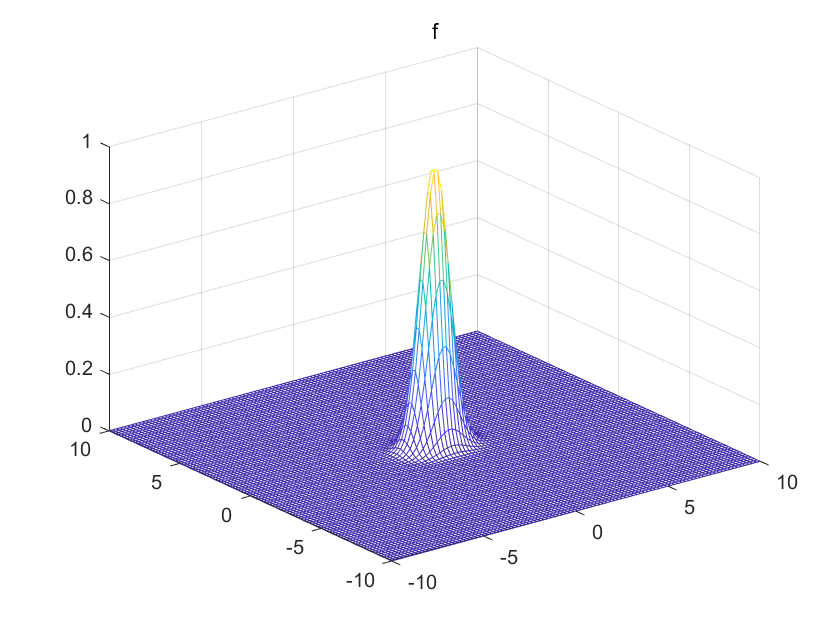

f = exp( -mx.^2 - 2*my.^2 );

figure;
mesh(mx,my,f);
title('f')

## using del2

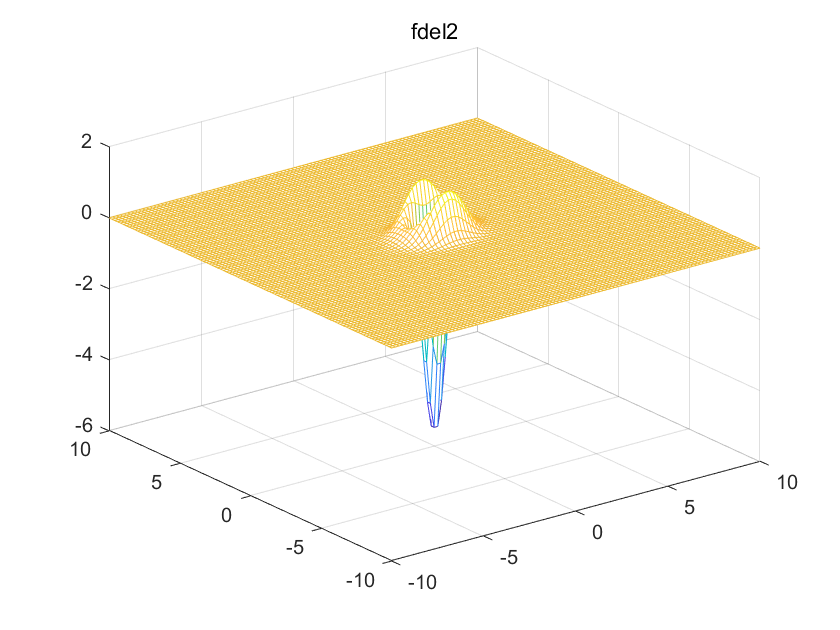

fdel2 = 4*del2(f,dx,dy);

figure;
mesh(mx,my,fdel2);
title('fdel2')

## use Five-point stencil ([https://en.wikipedia.org/wiki/Discrete_Laplace_operator](https://en.wikipedia.org/wiki/Discrete_Laplace_operator))

matrix5 = [0, 1, 0; 1, -4, 1; 0, 1, 0];
disp(matrix5)

     0     1     0
     1    -4     1
     0     1     0



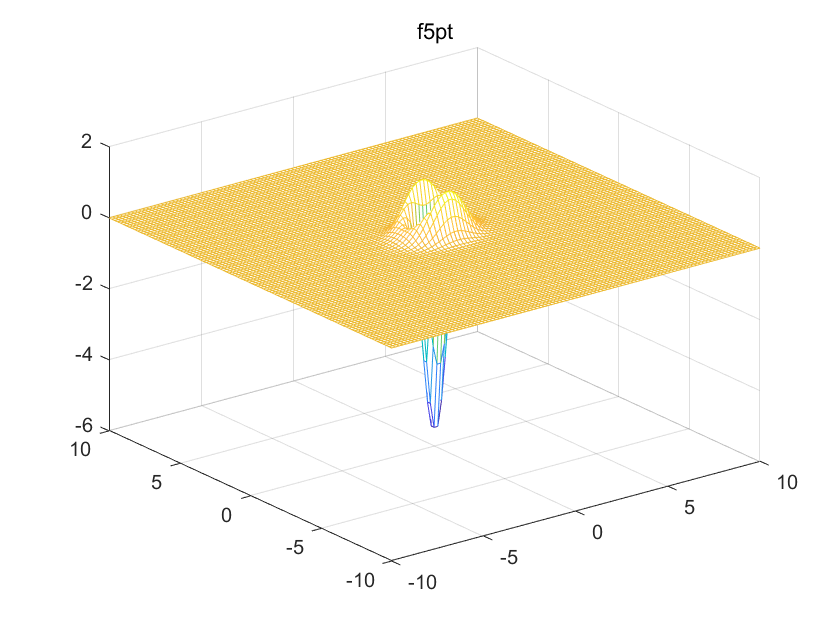


temp = conv2(f,matrix5,'valid')/dx/dy;
f5pt = zeros(Lx,Ly);
f5pt(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,f5pt);
title('f5pt')


% check the difference
diff5pt = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff5pt = -1.0914e-15

## use Nive-point stencil ([https://en.wikipedia.org/wiki/Discrete_Laplace_operator](https://en.wikipedia.org/wiki/Discrete_Laplace_operator))

matrix9 = [0.25, 0.5, 0.25; 0.5, -3, 0.5; 0.25, 0.5, 0.25];
disp(matrix9)

    0.2500    0.5000    0.2500
    0.5000   -3.0000    0.5000
    0.2500    0.5000    0.2500



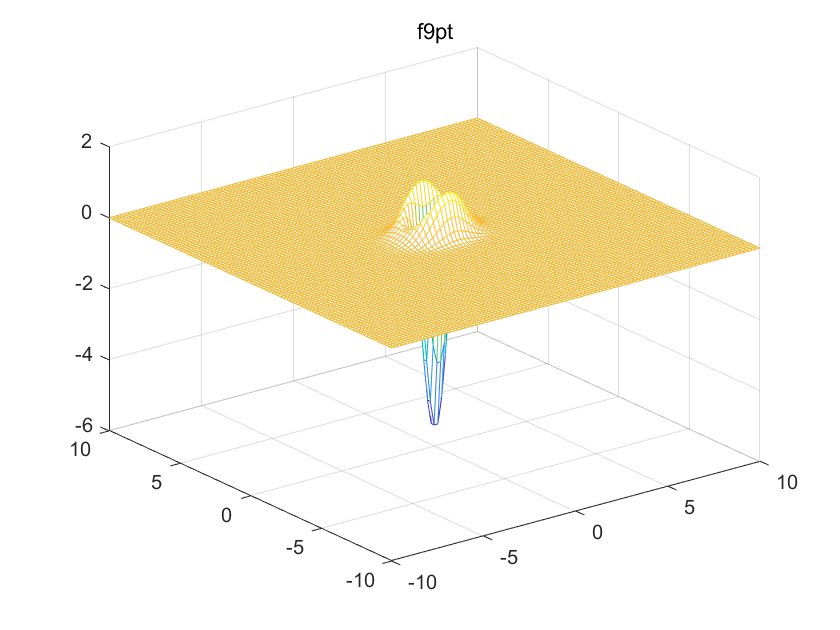


temp = conv2(f,matrix9,'valid')/dx/dy;
f9pt = zeros(Lx,Ly);
f9pt(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,f9pt);
title('f9pt')


% check the difference
diff9pt = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff9pt = 9.4175e-15

## use Nive-point stencil 2  ([https://core.ac.uk/download/pdf/81936845.pdf](https://core.ac.uk/download/pdf/81936845.pdf))

matrix9_2 = [1, 4, 1; 4, -20, 4; 1, 4, 1];
disp(matrix9_2)

     1     4     1
     4   -20     4
     1     4     1



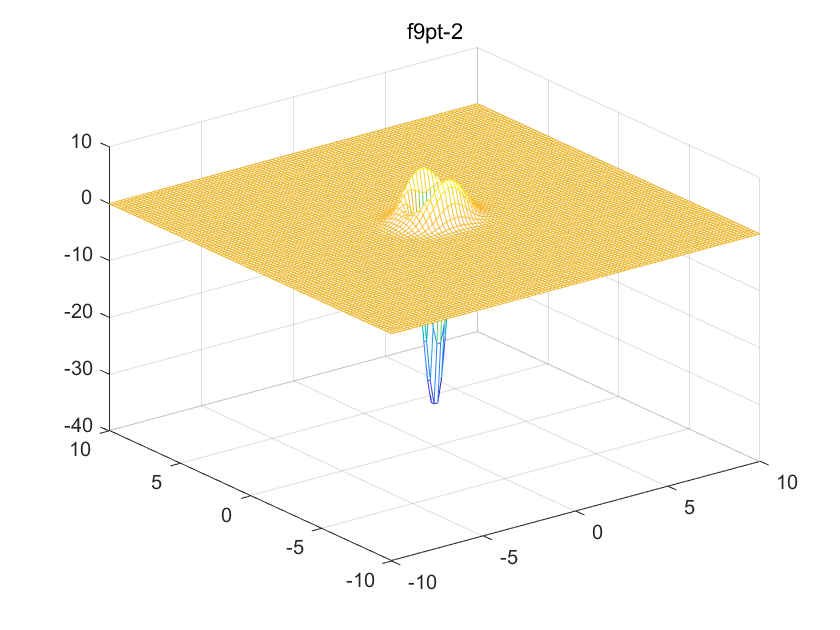


temp = conv2(f,matrix9_2,'valid')/dx/dy;
f9pt_2 = zeros(Lx,Ly);
f9pt_2(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,f9pt_2);
title('f9pt-2')


% check the difference
diff9pt_2 = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff9pt_2 = 2.0427e-13

## use Nive-point stencil 3  (https://www-m2.ma.tum.de/foswiki/pub/M2/Allgemeines/NumPro2CSESS13/tutorial_08_pde_finite_diff_2_solution.pdf)

matrix9_3 = [0 0 -1/12 0 0 ; ...
    0 0 4/3 0 0 ; ...
    -1/12 4/3 -5 4/3 -1/12; ...
    0 0 4/3 0 0 ; ...
    0 0 -1/12 0 0 ];
disp(matrix9_3)

         0         0   -0.0833         0         0
         0         0    1.3333         0         0
   -0.0833    1.3333   -5.0000    1.3333   -0.0833
         0         0    1.3333         0         0
         0         0   -0.0833         0         0



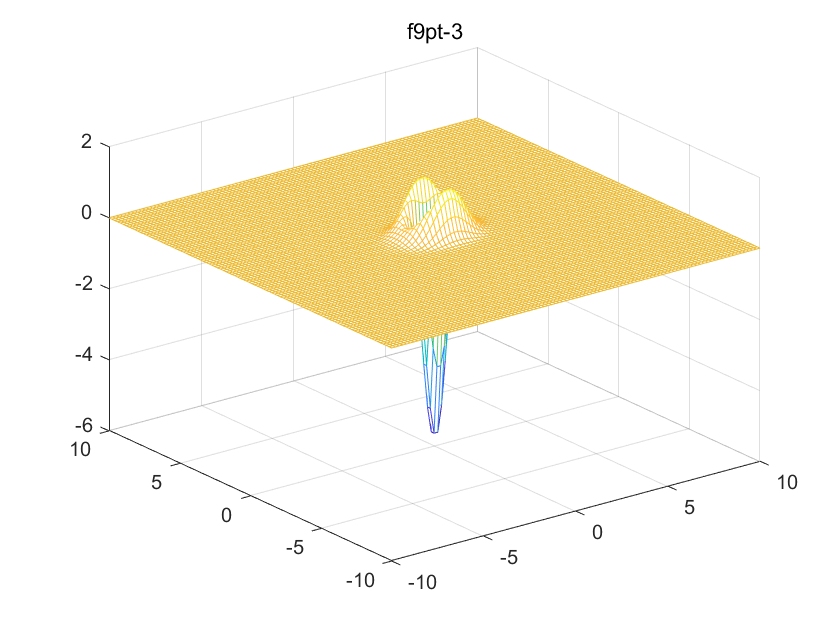


temp = conv2(f,matrix9_3,'valid')/dx/dy;
f9pt_3 = zeros(Lx,Ly);
f9pt_3(3:end-2,3:end-2)=temp;

figure;
mesh(mx,my,f9pt_3);
title('f9pt-3')


% check the difference
diff9pt_3 = sum(sum( fdel2(3:end-2,3:end-2) - temp ))

diff9pt_3 = 3.2576e-13